close all; 

g = 9.807; 
Ts = 0.005; 
plane_x = 30; 
%original time constant was too small and motion was not smooth enough
motion_time_constant = 0.005; 
contact_damping = 4000; 

zRobot = 0.78;
zModel = 0.68; 
swingHeight = 0.1; 

desiredStepTime = 0.8; 

% create a struct for helper functions to use 
robotParam.Ts = Ts; 
robotParam.zRobot = zRobot; 
robotParam.zModel = zModel; 

desiredFootTransforms = cell(6, 1); 
R = [0 -1 0;0 0 1;-1 0 0]; 
Tb_fl = Transform(-0.12, 0, 0, R);
Tb_fr = Transform( 0.12, 0, 0, R);
Tw_b = Transform(0, 0, 0); 

% Walk in straigt line 
desiredCapturePoints = [-0.12 0.1;
                         0.12 0.2;
                        -0.12 0.4;
                         0.12 0.5;
                        -0.12 0.5;
                         0.12 0.5]; 

% for now footholds and capture point EOS are same 
desiredfootholds     = desiredCapturePoints; 

### Create the Linear Inverted Pendulum Model

Create a discrete state-space model of the linear inverted pendulum.

w = sqrt(g/zModel); 
w2 = g/zModel; 
A = [0   1 0  0
     w2  0 0  0
     0   0 0  1
     0   0 w2 0]; 
B = [0  0
    -w2 0
     0  0
     0  -w2]; 
C = [1 0 0 0
     0 0 1 0]; 
D = [0 0;0 0]; 

lipm = ss(A,B,C,D); 
lipmD = c2d(lipm, Ts); 

Ad = lipmD.A; 
Bd = lipmD.B;
Cd = lipmD.C;
Dd = lipmD.D;

### Initial State

In this example, the robot will start walking with its center of mass (COM) positioned right above the right foot. 

x0  = 0.12; 
dx0 = 0; 
y0  = 0; 
dy0 = 0; 
state0 = [x0 dx0 y0 dy0]'; 
robotpos0 = [x0; y0; zModel]; 

xc = x0; 
yc = y0;
dxc = dx0; 
dyc = dy0; 
cpointx = xc + dxc/w; 
cpointy = yc + dyc/w; 


### Calculate ZMP based on next capture point EOS

cpdesired = desiredCapturePoints(1,:); %[-0.12 0.1];
px0 = findZMP(w, desiredStepTime, cpdesired(1), cpointx); 
py0 = findZMP(w, desiredStepTime, cpdesired(2), cpointy); 
u0 = [px0 py0]'; 

### Initialize Graphics

Graphics objects help us animate the model. 

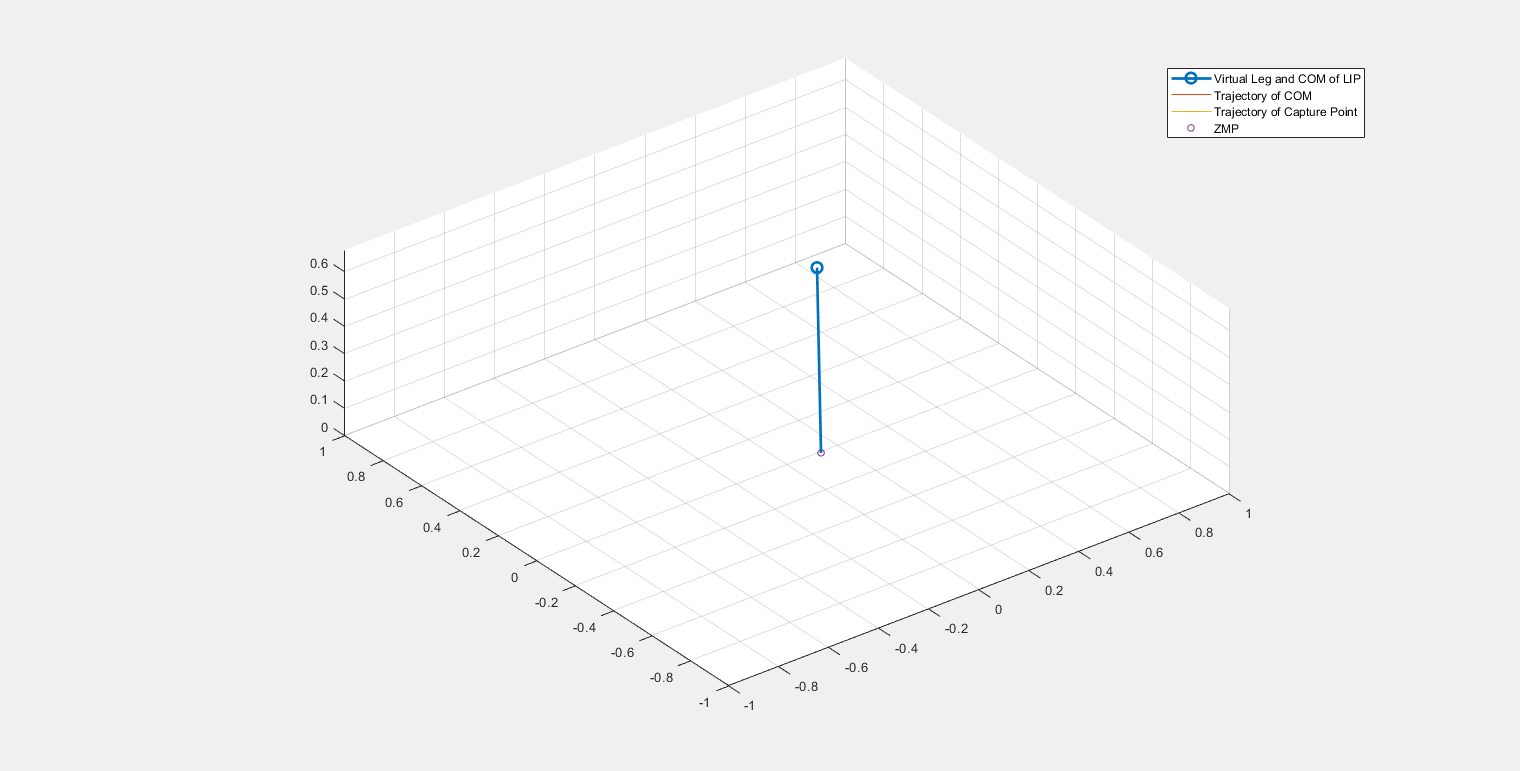

hFig = figure; 
hFig.Visible = 'on'; % for livescript 
hFig.Units = 'Normalized'; 
hFig.OuterPosition = [0.2 0.2 0.6 0.6]; 
hAx  = axes(hFig); 

% create handles for plots 
hold(hAx, 'on'); 
hLeg  = plot3(hAx,[px0,robotpos0(1)],[py0,robotpos0(2)],[0,robotpos0(3)],...
                '-o','MarkerIndices',2,'LineWidth',2,'MarkerSize',8); % represents com + leg 
hCom = plot3(hAx,robotpos0(1),robotpos0(2),robotpos0(3)); % represents com traj
hCap = plot3(hAx,cpointx,cpointy,0); % represents capture point traj 
hZMP = plot3(hAx,px0,py0,0,'o','MarkerSize',5); % represents ZMPs
% draw foot transform 
transformSize = 0.05; 
if walkStyle == 1
    [hI, hJ, hK] = desiredFootTransforms{1}.Draw(hAx, [0.466, 0.674, 0.188], transformSize); 
end

hold(hAx, 'off'); 

grid(hAx, 'on'); 
view(hAx, 3)
axis equal 
hAx.XLim = [-1 1]; 
hAx.YLim = [-1 1]; 
legend(hAx, 'Virtual Leg and COM of LIP','Trajectory of COM','Trajectory of Capture Point',...
    'ZMP','Location', 'northeast');   

### Simulate First Stance

zmppos = [px0; py0; 0]; 

for idx = 1:round(desiredStepTime/Ts)
    state1 = Ad*state0 + Bd*u0; 
    meas1  = Cd*state1 + Dd*u0; 
    state0 = state1; 
    
    xc = meas1(1); 
    yc = meas1(2);
    dxc = state1(2); 
    dyc = state1(4); 
    cpointx = xc + dxc/w; 
    cpointy = yc + dyc/w; 
    
    cappos = [cpointx; 
              cpointy; 
              0]; 
    bodypos = [xc; 
               yc; 
               zModel]; 
    points = [px0, bodypos(1);
              py0, bodypos(2);
              0,   bodypos(3)]; 
    % update graphics 
    updateLine(hLeg, points);
    appendLine(hCom, bodypos); 
    appendLine(hCap, cappos); 
    pause(0.005); 
end 

### Put the next base on Capture Point 

px = cpointx; 
py = cpointy; 
u0 = [px py]'; 
% update graphics
if walkStyle == 1
    desiredFootTransforms{stepidx}.UpdateDraw(hI, hJ, hK, transformSize); 
end 
zmppos = [px; py; 0]; 
appendLine(hZMP, zmppos);

Simulate Stance

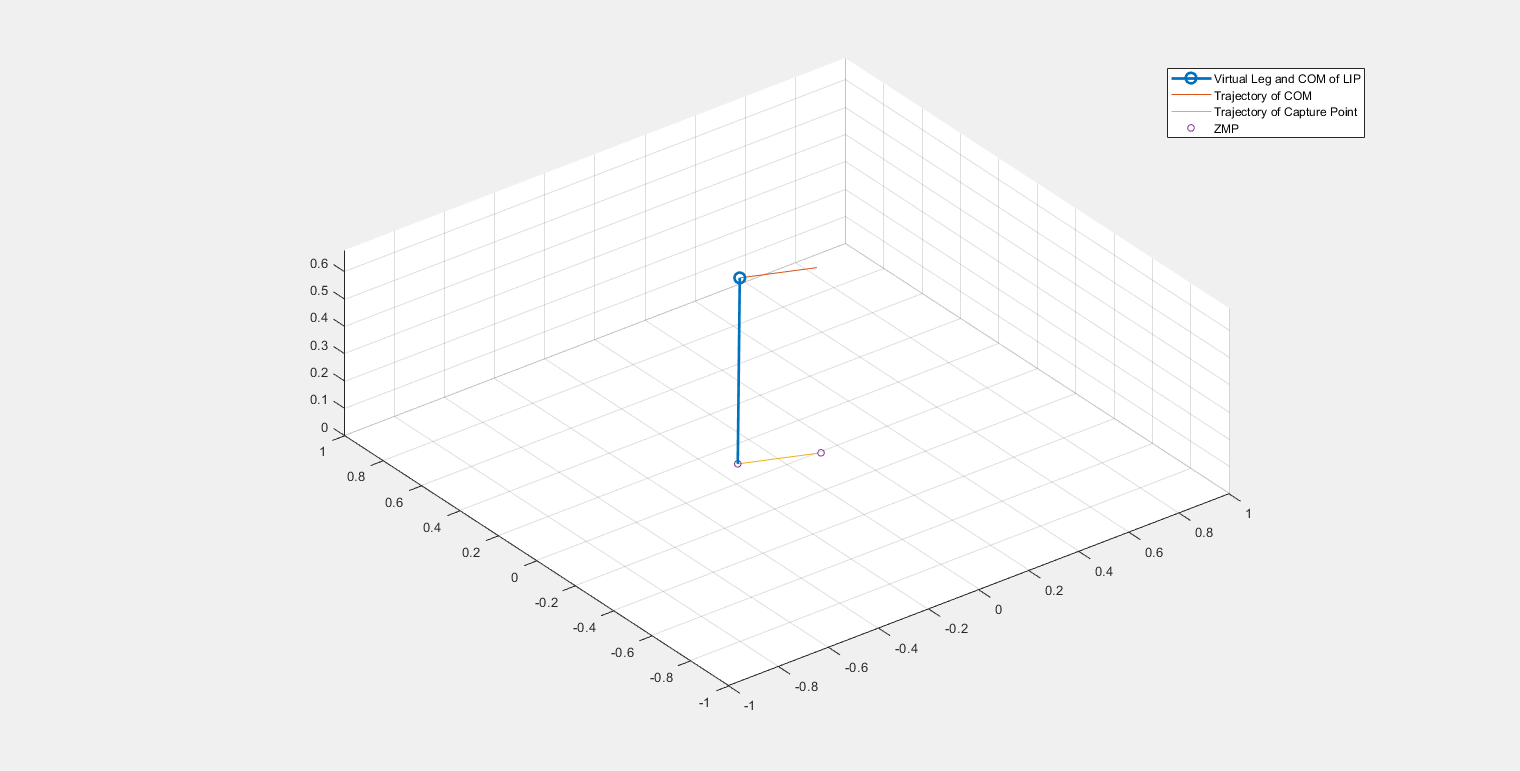

for idx = 1:round(desiredStepTime/Ts)
    state1 = Ad*state0 + Bd*u0; 
    meas1  = Cd*state1 + Dd*u0; 
    state0 = state1; 
    
    xc = meas1(1); 
    yc = meas1(2);
    dxc = state1(2); 
    dyc = state1(4); 
    cpointx = xc + dxc/w; 
    cpointy = yc + dyc/w; 
    
    cappos = [cpointx; 
              cpointy; 
              0]; 
    bodypos = [xc; 
               yc; 
               zModel]; 
    points = [px, bodypos(1);
              py, bodypos(2);
              0,  bodypos(3)]; 
    
    % update graphics 
    updateLine(hLeg, points);
    appendLine(hCom, bodypos); 
    appendLine(hCap, cappos); 
    pause(0.005); 
end 

function appendLine(gHandle, points)
    gHandle.XData(end+1) = points(1); 
    gHandle.YData(end+1) = points(2); 
    gHandle.ZData(end+1) = points(3); 
end 

Replaces points in a graphics line object

function updateLine(gHandle, points)
    gHandle.XData = points(1,:); 
    gHandle.YData = points(2,:); 
    gHandle.ZData = points(3,:); 
end